load AI_Models.mat
load DOE_LHS2000.mat
load dataTable_LHS2000.mat

Defining lower and upper bounds for all the design variables, for executing an optimization routine later in the script

designVar_CoreShaftInertia_lb = 0.05;
designVar_CoreShaftInertia_ub = 0.5;
designVar_CoreDampingCoeff_lb = 0.0005;
designVar_CoreDampingCoeff_ub = 0.005;
designVar_CombustorVolume_lb = 0.001;
designVar_CombustorVolume_ub = 0.01;
% designVar_FlowArea_lb = 0.005;
% designVar_FlowArea_ub = 0.5;
designVar_PTInertiaMultiplier_lb = 0.1;
designVar_PTInertiaMultiplier_ub = 0.8;
designVar_RotorInertiaMultiplier_lb = 0.1;
designVar_RotorInertiaMultiplier_ub = 0.8;
designVar_PTNozzleOpening_lb = 0.3;
designVar_PTNozzleOpening_ub = 1.0;
designVar_PTDampingCoeff_lb = 0.0005;
designVar_PTDampingCoeff_ub = 0.005;
designVar_RotorDampingCoeff_lb = 0.0005;
designVar_RotorDampingCoeff_ub = 0.005;
designVar_GearRatio_lb = 1.5;
designVar_GearRatio_ub = 6;

## Build full factorial design using ROM

Notice that in the current form DOE data is not fit for modelling a surface or for visualizing the design space through contours because of the sampling technique. To build these visualizations, a full factorial analysis is required which could be too resource extensive job in some applications involving simulations on physics based models. However now that we have ROMs for system responses, we can use these to investigate the entire design space.

    % Define the number of factors (parameters) and levels
    numFactors = 2;
    levels = 50;
    
    % Generate a full factorial design
    ffdesign = fullfact(repmat(levels, 1, numFactors));
    
    a = linspace(designVar_RotorDampingCoeff_lb,designVar_RotorDampingCoeff_ub,levels);
    b = linspace(designVar_GearRatio_lb,designVar_GearRatio_ub,levels);
    [A,B] = meshgrid(a,b);
     
    % The fullfact function makes it easy to generate Full Factorial sampling
    DOE = [a(ffdesign(:,1))' b(ffdesign(:,2))'];
    
    % Display the size of the design
    disp(['Size of the full factorial design: ' num2str(size(ffdesign))]);

Size of the full factorial design: 2500     2


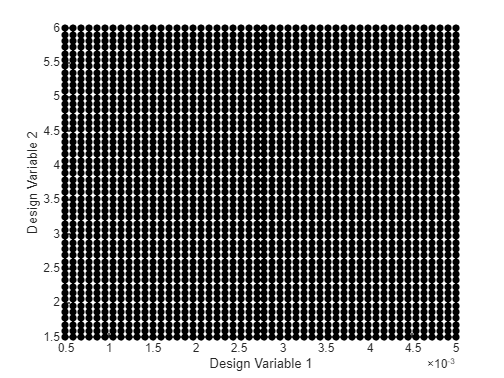

figure;
scatter(DOE(:,1),DOE(:,2),'k','filled')
xlabel('Design Variable 1')
ylabel('Design Variable 2')

## **ROM-based interpolation for system responses**

**As a stastician, or even being a domain expert, we can identify the 2 most important features affecting our system responses/ objectives. Idea here is to build refined parametric space in 2D so that we can project the 9-dimesional design space on to a 2D contour with the 2 important design features on x and y axes.**

responseShaftPower = zeros(size(A));
responseThrustCore = zeros(size(A));
responseThrustPT = zeros(size(A));
responseHeatInput = zeros(size(A));
responseTurbineNozzleOpening = zeros(size(A));

% tbl = array2table(zeros(1,9));
% tbl.Properties.VariableNames = dataTable.Properties.VariableNames(1:9);
rng default
randomRowIndex = randi(height(dataTable)); % random Row for defining fixed values for other 7 variables
% fixedVariables = dataTable(randomRowIndex,{'CoreInertia','CoreDamping','CombustorVolume','PTInertia','RotorInertia','PTNozzleOpening','PTDamping'})
fixedVariables = dataTable(randomRowIndex,1:9);
tbl = fixedVariables;

% fixedVariables.PTNozzleOpening = 0.5;

for i = 1:width(a)
    for j = 1:width(b)
        tbl.RotorDamping = a(i);
        tbl.GearRatio = b(j);
        responseShaftPower(j,i) = NN_ShaftPower.predictFcn(tbl);
        responseThrustCore(j,i) = NN_ThrustCore.predictFcn(tbl);
        responseThrustPT(j,i) = NN_ThrustPT.predictFcn(tbl);
        responseHeatInput(j,i) = NN_HeatInput.predictFcn(tbl);
        responseTurbineNozzleOpening(j,i) = NN_TurbNozzleOpening.predictFcn(tbl);
    end
end

# Design Space Exploration

Let's try to visualize the feasible design space through contour plots. Assume design constraints on shaft power, core thrust, power turbine thrust, heat input and turbine nozzle opening.

                                                    
$$\begin{array}{l}
\textrm{Shaft}\;P\textrm{ower}\ge 5000\;W\\
\textrm{Core}\;\textrm{Thrust}\ge 150\;N\;\\
\textrm{Power}\;\textrm{Turbine}\;\textrm{Thrust}\ge 1000\;N
\end{array}$$


constraint_ShaftPower = 5000; % Watts
constraint_ThrustCore = 150; % N
constraint_ThrustPT = 1000; %N
constraints = [constraint_ShaftPower constraint_ThrustCore constraint_ThrustPT];

figure;
[CShaftPower,hShaftPower] = contour(A,B,responseShaftPower,[constraint_ShaftPower-500 constraint_ShaftPower constraint_ShaftPower+500],'ShowText','on','EdgeColor','r',"LabelFormat","%0.0f W");
clabel(CShaftPower,hShaftPower,'FontSize',10,'Color','red')
hold on
[CThrustCore,hThrustCore] = contour(A,B,responseThrustCore,[constraint_ThrustCore-50 constraint_ThrustCore constraint_ThrustCore+50],'ShowText','on','EdgeColor','k',"LabelFormat","%0.0f N");
clabel(CThrustCore,hThrustCore,'FontSize',10,'Color','k')
[CThrustPT,hThrustPT] = contour(A,B,responseThrustPT,[constraint_ThrustPT-200 constraint_ThrustPT constraint_ThrustPT+200],'ShowText','on','EdgeColor','b',"LabelFormat","%0.0f N");
clabel(CThrustPT,hThrustPT,'FontSize',10,'Color','b')
feasibleDesignSpace = responseShaftPower >= constraint_ShaftPower & responseThrustCore >= constraint_ThrustCore & responseThrustPT >= constraint_ThrustPT;
scatter(A(feasibleDesignSpace),B(feasibleDesignSpace),'filled','o','MarkerFaceColor',[0 0.8 0.6],'MarkerFaceAlpha',0.2)
xlabel('Rotor Damping (N-m-s/rad)')
ylabel('Gear Ratio #')
title('Feasible Design Space (ROM)')
hold off
legend('Shaft Power','Core Thrust','Power Turbine Thrust', 'Design Space','location','northwest')

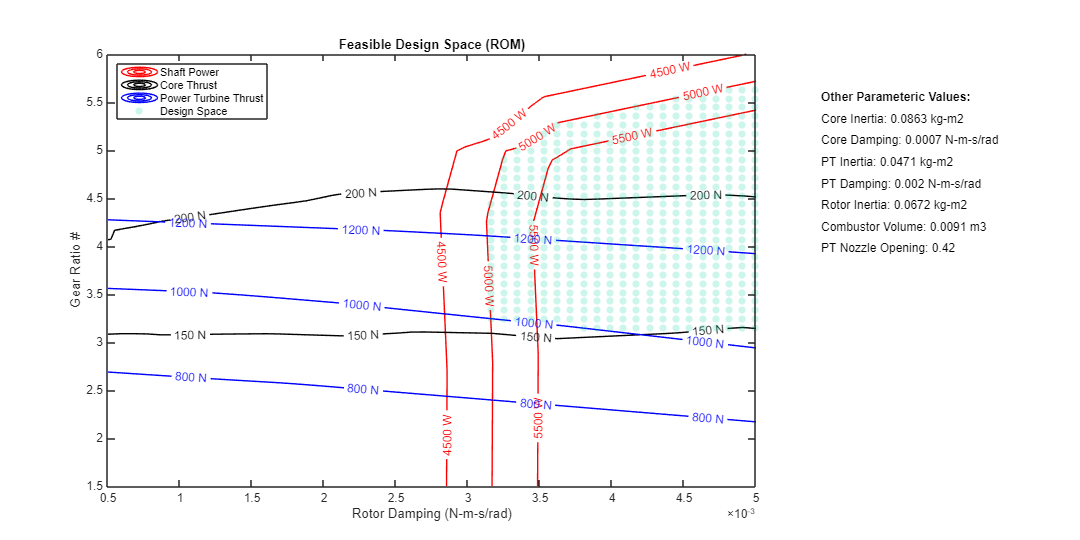

% Adjust the plot position to make space for the text
set(gca, 'Position', [0.1, 0.1, 0.6, 0.8]);
set(gcf,'Position',[10 10 1200 600]);
% Get current axes limits
xlims = xlim;
ylims = ylim;

% Add text using the text function
str = 'Other Parameteric Values:';
strCoreInertia = ['Core Inertia: ',num2str(round(fixedVariables.CoreInertia,4)),' kg-m2'];
strCoreDamping = ['Core Damping: ',num2str(round(fixedVariables.CoreDamping,4)),' N-m-s/rad'];
strPTInertia = ['PT Inertia: ',num2str(round(fixedVariables.PTInertia,4)),' kg-m2'];
strPTDamping = ['PT Damping: ',num2str(round(fixedVariables.PTDamping,4)),' N-m-s/rad'];
strRotorInertia = ['Rotor Inertia: ',num2str(round(fixedVariables.RotorInertia,4)),' kg-m2'];
strCombustorVolume = ['Combustor Volume: ',num2str(round(fixedVariables.CombustorVolume,4)),' m3'];
strPTNozzleOpening = ['PT Nozzle Opening: ',num2str(round(fixedVariables.PTNozzleOpening,2)),''];

text(xlims(2) + (xlims(2)-xlims(1))*0.1, (ylims(2) - (ylims(2)-ylims(1))*0.1), str, 'HorizontalAlignment', 'left','FontWeight','bold');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.15), strCoreInertia, 'HorizontalAlignment', 'left');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.20), strCoreDamping, 'HorizontalAlignment', 'left');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.25), strPTInertia, 'HorizontalAlignment', 'left');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.3), strPTDamping, 'HorizontalAlignment', 'left');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.35), strRotorInertia, 'HorizontalAlignment', 'left');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.4), strCombustorVolume, 'HorizontalAlignment', 'left');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.45), strPTNozzleOpening, 'HorizontalAlignment', 'left');

**Dynamic Design Space**

responseShaftPower = zeros(size(A));
responseThrustCore = zeros(size(A));
responseThrustPT = zeros(size(A));
responseHeatInput = zeros(size(A));
responseTurbineNozzleOpening = zeros(size(A));

% tbl = array2table(zeros(1,9));
% tbl.Properties.VariableNames = dataTable.Properties.VariableNames(1:9);
rng default
randomRowIndex = randi(height(dataTable)); % random Row for defining fixed values for other 7 variables
% fixedVariables = dataTable(randomRowIndex,{'CoreInertia','CoreDamping','CombustorVolume','PTInertia','RotorInertia','PTNozzleOpening','PTDamping'})
fixedVariables = dataTable(randomRowIndex,1:9);
figure;

for k=1:10 % 10 iterations changing the fixed variables
tbl = fixedVariables;
tbl.PTNozzleOpening = fixedVariables.PTNozzleOpening+0.01*k;

for i = 1:width(a)
    for j = 1:width(b)
        tbl.RotorDamping = a(i);
        tbl.GearRatio = b(j);
        responseShaftPower(j,i) = NN_ShaftPower.predictFcn(tbl);
        responseThrustCore(j,i) = NN_ThrustCore.predictFcn(tbl);
        responseThrustPT(j,i) = NN_ThrustPT.predictFcn(tbl);
        responseHeatInput(j,i) = NN_HeatInput.predictFcn(tbl);
        responseTurbineNozzleOpening(j,i) = NN_TurbNozzleOpening.predictFcn(tbl);
    end
end

constraint_ShaftPower = 5000; % Watts
constraint_ThrustCore = 150; % N
constraint_ThrustPT = 1000; %N
constraints = [constraint_ShaftPower constraint_ThrustCore constraint_ThrustPT];

cla
[CShaftPower,hShaftPower] = contour(A,B,responseShaftPower,[constraint_ShaftPower-500 constraint_ShaftPower constraint_ShaftPower+500],'ShowText','on','EdgeColor','r',"LabelFormat","%0.0f W");
clabel(CShaftPower,hShaftPower,'FontSize',10,'Color','red')
hold on
[CThrustCore,hThrustCore] = contour(A,B,responseThrustCore,[constraint_ThrustCore-50 constraint_ThrustCore constraint_ThrustCore+50],'ShowText','on','EdgeColor','k',"LabelFormat","%0.0f N");
clabel(CThrustCore,hThrustCore,'FontSize',10,'Color','k')
[CThrustPT,hThrustPT] = contour(A,B,responseThrustPT,[constraint_ThrustPT-200 constraint_ThrustPT constraint_ThrustPT+200],'ShowText','on','EdgeColor','b',"LabelFormat","%0.0f N");
clabel(CThrustPT,hThrustPT,'FontSize',10,'Color','b')
feasibleDesignSpace = responseShaftPower >= constraint_ShaftPower & responseThrustCore >= constraint_ThrustCore & responseThrustPT >= constraint_ThrustPT;
scatter(A(feasibleDesignSpace),B(feasibleDesignSpace),'filled','o','MarkerFaceColor',[0 0.8 0.6],'MarkerFaceAlpha',0.2)
xlabel('Rotor Damping (N-m-s/rad)')
ylabel('Gear Ratio #')
title('Feasible Design Space (ROM)')
hold off

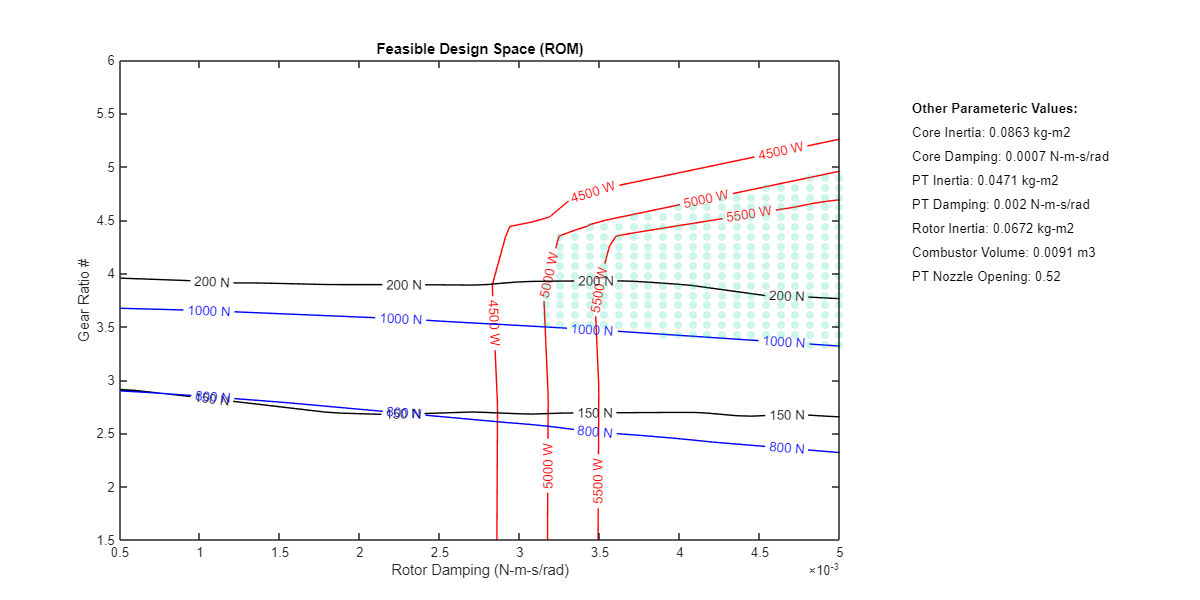

% Adjust the plot position to make space for the text
set(gca, 'Position', [0.1, 0.1, 0.6, 0.8]);
set(gcf,'Position',[10 10 1200 600]);
% Get current axes limits
xlims = xlim;
ylims = ylim;

% Add text using the text function
str = 'Other Parameteric Values:';
strCoreInertia = ['Core Inertia: ',num2str(round(fixedVariables.CoreInertia,4)),' kg-m2'];
strCoreDamping = ['Core Damping: ',num2str(round(fixedVariables.CoreDamping,4)),' N-m-s/rad'];
strPTInertia = ['PT Inertia: ',num2str(round(fixedVariables.PTInertia,4)),' kg-m2'];
strPTDamping = ['PT Damping: ',num2str(round(fixedVariables.PTDamping,4)),' N-m-s/rad'];
strRotorInertia = ['Rotor Inertia: ',num2str(round(fixedVariables.RotorInertia,4)),' kg-m2'];
strCombustorVolume = ['Combustor Volume: ',num2str(round(fixedVariables.CombustorVolume,4)),' m3'];
strPTNozzleOpening = ['PT Nozzle Opening: ',num2str(round(tbl.PTNozzleOpening,2)),''];

text(xlims(2) + (xlims(2)-xlims(1))*0.1, (ylims(2) - (ylims(2)-ylims(1))*0.1), str, 'HorizontalAlignment', 'left','FontWeight','bold');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.15), strCoreInertia, 'HorizontalAlignment', 'left');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.20), strCoreDamping, 'HorizontalAlignment', 'left');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.25), strPTInertia, 'HorizontalAlignment', 'left');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.3), strPTDamping, 'HorizontalAlignment', 'left');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.35), strRotorInertia, 'HorizontalAlignment', 'left');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.4), strCombustorVolume, 'HorizontalAlignment', 'left');
text((xlims(2) + (xlims(2)-xlims(1))*0.1), (ylims(2) - (ylims(2)-ylims(1))*0.45), strPTNozzleOpening, 'HorizontalAlignment', 'left');
drawnow limitrate
end

**Actual simulation data** for the one chosen point in the LHS sampling

for ii = height(ffdesign):-1:1
% for ii = 100:-1:1
    simInNew (ii) = Simulink.SimulationInput('TurboShaftEngine_mod');
    simInNew (ii) = simInNew (ii).setVariable('Core_Shaft_inertia',fixedVariables.CoreInertia);
    simInNew (ii) = simInNew (ii).setVariable('Core_Damping_Coeff',fixedVariables.CoreDamping);
    simInNew (ii) = simInNew (ii).setVariable('Combustor_volume',fixedVariables.CombustorVolume);
    simInNew (ii) = simInNew (ii).setVariable('Flow_area',0.01);
    simInNew (ii) = simInNew (ii).setVariable('PT_Shaft_inertia',fixedVariables.PTInertia);
    simInNew (ii) = simInNew (ii).setVariable('PT_Nozzle_Opening',fixedVariables.PTNozzleOpening);
    simInNew (ii) = simInNew (ii).setVariable('PT_Damping_Coeff',fixedVariables.PTDamping);
    simInNew (ii) = simInNew (ii).setVariable('Rotor_Damping_Coeff',DOE(ii,1));
    simInNew (ii) = simInNew (ii).setVariable('GearRatio',DOE(ii,2));
    simInNew (ii) = simInNew (ii).setVariable('Rotor_Inertia',fixedVariables.RotorInertia);
end

try
    out = parsim(simInNew , 'TransferBaseWorkspaceVariables', 'on', 'ShowProgress', true, 'UseFastRestart', false,'ShowSimulationManager','on')
catch ME
    % Handle errors
    fprintf('An error occurred during simulation: %s\n', ME.message);
    % ... additional error handling ...
end

[19-Feb-2024 00:44:45] Checking for availability of parallel pool...
[19-Feb-2024 00:44:46] Starting Simulink on parallel workers...
[19-Feb-2024 00:45:01] Configuring simulation cache folder on parallel workers...
[19-Feb-2024 00:45:02] Transferring base workspace variables used in the model to parallel workers...
[19-Feb-2024 00:45:21] Loading model on parallel workers...
[19-Feb-2024 00:45:57] Running simulations...


[19-Feb-2024 04:19:26] Cleaning up parallel workers...


out = 1x2500 Simulink.SimulationOutput array



**Log Simulation Results into Data Table**

j=1;
for i=1:height(out')
    if isempty(out(1,i).ErrorMessage)
        Time = timeseries2timetable(out(1,i).logsout{1}.Values).Time;
        heatInput = timeseries2timetable(out(1,i).logsout{1}.Values);
        nozzleOpening = timeseries2timetable(out(1,i).logsout{2}.Values);
        power = timeseries2timetable(out(1,i).logsout{3}.Values);
        efficiency = timeseries2timetable(out(1,i).logsout{4}.Values);
        % Simscape Results
        fullResults = out(1, i).simlog_TurboShaftEngine.TurboShaftEngine;
        
        CoreTurbine_FluidPower = values(fullResults.CoreTurbine.fluid_power.series);
        Compressor_FluidPower = values(fullResults.Compressor.fluid_power.series);
        CorePower = (CoreTurbine_FluidPower - Compressor_FluidPower)*1000; % in Watts or N-m/sec
        TurbineOutletVelocity = abs(values(fullResults.CoreTurbine.outlet_velocity.series)); % in m/sec
        Thrust_Core = CorePower ./ TurbineOutletVelocity;

        PT_FluidPower = values(fullResults.PowerTurbine.fluid_power.series)*1000; % in Watts or N-m/sec
        PTOutletVelocity = abs(values(fullResults.PowerTurbine.outlet_velocity.series)); % in m/sec
        Thrust_PT = PT_FluidPower ./ PTOutletVelocity;

        Thrust_Net = Thrust_Core+Thrust_PT;
        Thrust_Net = table(Time, Thrust_Net);
        Thrust_Net = table2timetable(Thrust_Net);

        Thrust_PT = table2timetable(table(Time, Thrust_PT));
        Thrust_Core = table2timetable(table(Time, Thrust_Core));


        simOutNew(j,1:8) = table(i,{heatInput},{nozzleOpening},{power},{efficiency},...
                              {Thrust_Core},{Thrust_PT},{Thrust_Net});

        j=j+1;
    end
end
simOutNew.Properties.VariableNames = {'RunID','HeatInput_kW','TurbineNozzleOpening','ShaftPower_kW','ShaftMechEfficiency','Thrust','ThrustPT','ThrustNet_N'};

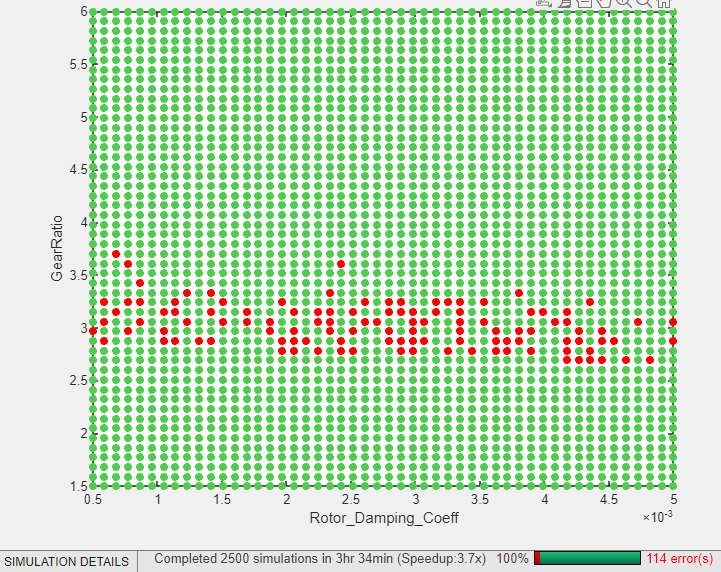

Extract mean values of System outputs at steady state conditions (t>=600sec)

simOutSSTableNew = array2table(zeros(height(simOutNew),width(simOutNew)-1));
simOutSSTableNew.Properties.VariableNames = simOutNew.Properties.VariableNames(2:end);
for i= 1:height(simOutNew)
    idx = simOutNew.HeatInput_kW{i,1}.Time>=seconds(600);
    simOutSSTableNew.HeatInput_kW(i)=mean(simOutNew.HeatInput_kW{i,1}.Heat_Input(idx));
    simOutSSTableNew.TurbineNozzleOpening(i)=mean(simOutNew.TurbineNozzleOpening{i,1}.NozzleOpening(idx));
    simOutSSTableNew.ShaftPower_kW(i)=mean(simOutNew.ShaftPower_kW{i,1}.Data(idx));
    simOutSSTableNew.ShaftMechEfficiency(i)=mean(simOutNew.ShaftMechEfficiency{i,1}.Data(idx));
    simOutSSTableNew.Thrust(i)=mean(simOutNew.Thrust{i,1}.Thrust_Core(idx));
    simOutSSTableNew.ThrustPT(i)=mean(simOutNew.ThrustPT{i,1}.Thrust_PT(idx));
    simOutSSTableNew.ThrustNet_N(i)=mean(simOutNew.ThrustNet_N{i,1}.Thrust_Net(idx));
end

% Only retain succesful execution from the DOE
designVariablesNew = tbl;
designVariablesNew = repmat(designVariablesNew,[height(simOutNew) 1]);
designVariablesNew.RotorDamping = DOE(simOutNew.RunID,1);
designVariablesNew.GearRatio = DOE(simOutNew.RunID,2);

save 3DSection designVariablesNew simOutNew simOutSSTableNew a b A B responseShaftPower responseThrustCore responseThrustPT responseHeatInput responseTurbineNozzleOpening

Use scatteredInterpolant to visualize response surface from the new DOE runs

F_ShaftPower = scatteredInterpolant(designVariablesNew.RotorDamping,designVariablesNew.GearRatio,simOutSSTableNew.ShaftPower_kW);
F_ThrustCore = scatteredInterpolant(designVariablesNew.RotorDamping,designVariablesNew.GearRatio,simOutSSTableNew.Thrust);
F_ThrustPT = scatteredInterpolant(designVariablesNew.RotorDamping,designVariablesNew.GearRatio,simOutSSTableNew.ThrustPT);
F_HeatInput = scatteredInterpolant(designVariablesNew.RotorDamping,designVariablesNew.GearRatio,simOutSSTableNew.HeatInput_kW);
F_TurbineNozzleOpening = scatteredInterpolant(designVariablesNew.RotorDamping,designVariablesNew.GearRatio,simOutSSTableNew.TurbineNozzleOpening);
RS_Sim_ShaftPower = F_ShaftPower(A,B);
RS_Sim_ThrustCore = F_ThrustCore(A,B);
RS_Sim_ThrustPT = F_ThrustPT(A,B);
RS_Sim_HeatInput = F_HeatInput(A,B);
RS_Sim_TurbineNozzleOpening = F_TurbineNozzleOpening(A,B);

**Visualization**

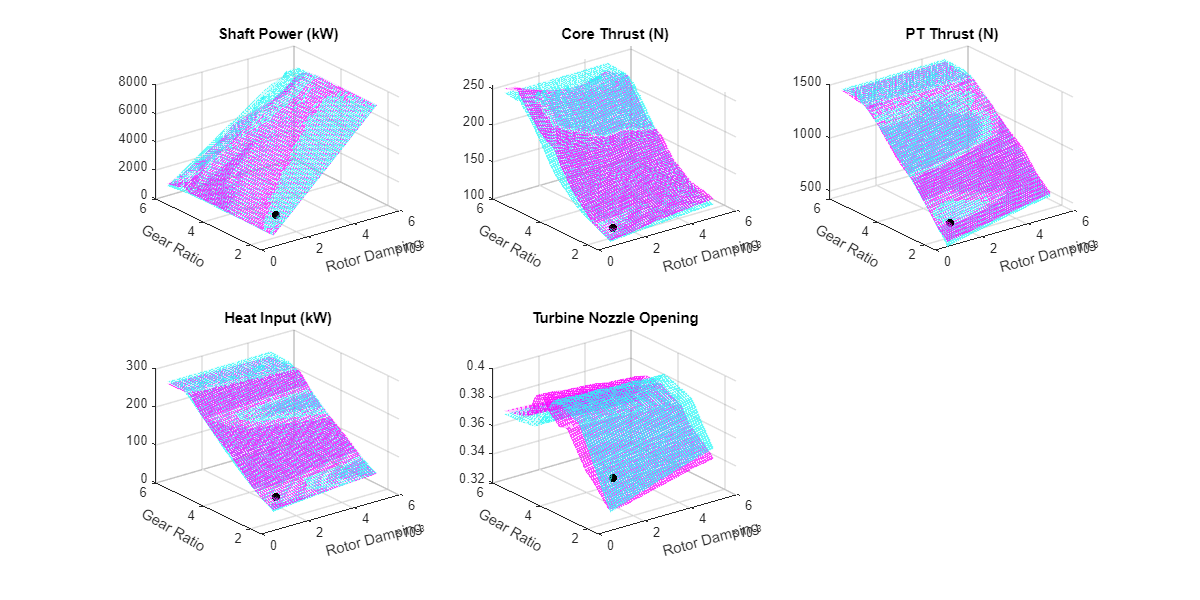

format long
colAI = 'magenta'; % Shade of Blue 86CAFA
colSim = '#2BF8F6'; % Shade of Red F39E72
alphaFace = 0.7;
alphaEdge = 0.1;
xlabelRot = 15;
ylabelRot = -30;
figure;
subplot(231)
surf(A,B,responseShaftPower,'FaceColor',colAI,'FaceAlpha',alphaFace,'EdgeColor',colAI,'EdgeAlpha',alphaEdge);
xlabel('Rotor Damping','Rotation',xlabelRot);
ylabel('Gear Ratio','Rotation',ylabelRot);
title('Shaft Power (kW)');
hold on
% scatter3(designVariablesNew.RotorDamping,designVariablesNew.GearRatio,simOutSSTableNew.ShaftPower_kW,'magenta','.');
mesh(A,B,RS_Sim_ShaftPower,'FaceColor',colSim,'FaceAlpha',alphaFace,'EdgeColor',colSim,'EdgeAlpha',alphaEdge);
scatter3(fixedVariables.RotorDamping,fixedVariables.GearRatio,dataTable.ShaftPower_kW(randomRowIndex),'k','filled')
ax = gca;
% % Set the axis number format to show two decimal places
% ax.XAxis.TickLabelFormat = '%0.4f';
% ax.YAxis.TickLabelFormat = '%.2f';
% ax.ZAxis.TickLabelFormat = '%.2f';
hold off

subplot(232)
surf(A,B,responseThrustCore,'FaceColor',colAI,'FaceAlpha',alphaFace,'EdgeColor',colAI,'EdgeAlpha',alphaEdge);
xlabel('Rotor Damping','Rotation',xlabelRot);
ylabel('Gear Ratio','Rotation',ylabelRot);
title('Core Thrust (N)');
hold on
% scatter3(designVariablesNew.RotorDamping,designVariablesNew.GearRatio,simOutSSTableNew.Thrust,'magenta','.');
mesh(A,B,RS_Sim_ThrustCore,'FaceColor',colSim,'FaceAlpha',alphaFace,'EdgeColor',colSim,'EdgeAlpha',alphaEdge);
scatter3(fixedVariables.RotorDamping,fixedVariables.GearRatio,dataTable.Thrust(randomRowIndex),'k','filled')
hold off

subplot(233)
surf(A,B,responseThrustPT,'FaceColor',colAI,'FaceAlpha',alphaFace,'EdgeColor',colAI,'EdgeAlpha',alphaEdge);
xlabel('Rotor Damping','Rotation',xlabelRot);
ylabel('Gear Ratio','Rotation',ylabelRot);
title('PT Thrust (N)');
hold on
% scatter3(designVariablesNew.RotorDamping,designVariablesNew.GearRatio,simOutSSTableNew.ThrustPT,'magenta','.');
mesh(A,B,RS_Sim_ThrustPT,'FaceColor',colSim,'FaceAlpha',alphaFace,'EdgeColor',colSim,'EdgeAlpha',alphaEdge);
scatter3(fixedVariables.RotorDamping,fixedVariables.GearRatio,dataTable.ThrustPT(randomRowIndex),'k','filled')
hold off

subplot(234)
surf(A,B,responseHeatInput,'FaceColor',colAI,'FaceAlpha',alphaFace,'EdgeColor',colAI,'EdgeAlpha',alphaEdge);
xlabel('Rotor Damping','Rotation',xlabelRot);
ylabel('Gear Ratio','Rotation',ylabelRot);
title('Heat Input (kW)');
hold on
% scatter3(designVariablesNew.RotorDamping,designVariablesNew.GearRatio,simOutSSTableNew.HeatInput_kW,'magenta','.');
mesh(A,B,RS_Sim_HeatInput,'FaceColor',colSim,'FaceAlpha',alphaFace,'EdgeColor',colSim,'EdgeAlpha',alphaEdge);
scatter3(fixedVariables.RotorDamping,fixedVariables.GearRatio,dataTable.HeatInput_kW(randomRowIndex),'k','filled')
hold off

subplot(235)
surf(A,B,responseTurbineNozzleOpening,'FaceColor',colAI,'FaceAlpha',alphaFace,'EdgeColor',colAI,'EdgeAlpha',alphaEdge);
xlabel('Rotor Damping','Rotation',xlabelRot);
ylabel('Gear Ratio','Rotation',ylabelRot);
title('Turbine Nozzle Opening');
hold on
% scatter3(designVariablesNew.RotorDamping,designVariablesNew.GearRatio,simOutSSTableNew.TurbineNozzleOpening,'magenta','.');
mesh(A,B,RS_Sim_TurbineNozzleOpening,'FaceColor',colSim,'FaceAlpha',alphaFace,'EdgeColor',colSim,'EdgeAlpha',alphaEdge);
scatter3(fixedVariables.RotorDamping,fixedVariables.GearRatio,dataTable.TurbineNozzleOpening(randomRowIndex),'k','filled')
hold off

% colorbar;
set(gcf,'Position',[10 10 1200 600]);

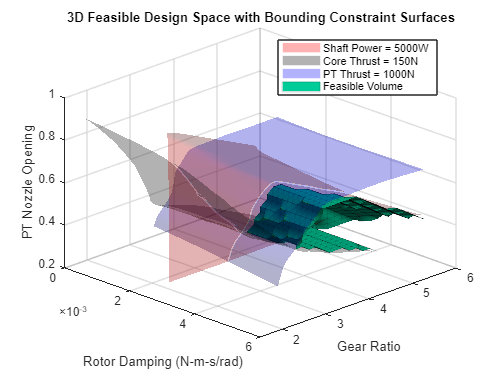

% Define grid resolution
n = 30;  % Finer means smoother but slower

% Create 3D grid
xVals = linspace(designVar_RotorDampingCoeff_lb, designVar_RotorDampingCoeff_ub, n);  % Rotor Damping
yVals = linspace(designVar_GearRatio_lb, designVar_GearRatio_ub, n);                  % Gear Ratio
zVals = linspace(0.3, 1.0, n);                                                        % PT Nozzle Opening

[X, Y, Z] = meshgrid(xVals, yVals, zVals);

% Initialize response volumes
V_sp = zeros(size(X));  % Shaft Power
V_tc = zeros(size(X));  % Core Thrust
V_pt = zeros(size(X));  % PT Thrust

% Loop through all grid points
for i = 1:n
    for j = 1:n
        for k = 1:n
            tbl = fixedVariables;
            tbl.RotorDamping = X(i,j,k);
            tbl.GearRatio = Y(i,j,k);
            tbl.PTNozzleOpening = Z(i,j,k);

            V_sp(i,j,k) = NN_ShaftPower.predictFcn(tbl);
            V_tc(i,j,k) = NN_ThrustCore.predictFcn(tbl);
            V_pt(i,j,k) = NN_ThrustPT.predictFcn(tbl);
        end
    end
end

% Plot bounding surfaces
figure;
hold on;

% Shaft Power Constraint Surface
p1 = patch(isosurface(X, Y, Z, V_sp, constraint_ShaftPower));
set(p1, 'FaceColor', 'red', 'EdgeColor', 'none', 'FaceAlpha', 0.3);

% Core Thrust Constraint Surface
p2 = patch(isosurface(X, Y, Z, V_tc, constraint_ThrustCore));
set(p2, 'FaceColor', 'black', 'EdgeColor', 'none', 'FaceAlpha', 0.3);

% PT Thrust Constraint Surface
p3 = patch(isosurface(X, Y, Z, V_pt, constraint_ThrustPT));
set(p3, 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.3);

% Optional: plot feasible volume inside
feasible = V_sp >= constraint_ShaftPower & V_tc >= constraint_ThrustCore & V_pt >= constraint_ThrustPT;
p4 = patch(isosurface(X, Y, Z, feasible, 0.99));  % 0.99 since true=1
set(p4, 'FaceColor', [0 0.8 0.6], 'EdgeAlpha', '0.1');

% Labels and appearance
xlabel('Rotor Damping (N-m-s/rad)');
ylabel('Gear Ratio');
zlabel('PT Nozzle Opening');
title('3D Feasible Design Space with Bounding Constraint Surfaces');

view(45,30);
camlight;
lighting gouraud;
grid on;
legend([p1 p2 p3 p4], {'Shaft Power = 5000W', 'Core Thrust = 150N', 'PT Thrust = 1000N', 'Feasible Volume'}, 'Location', 'best');

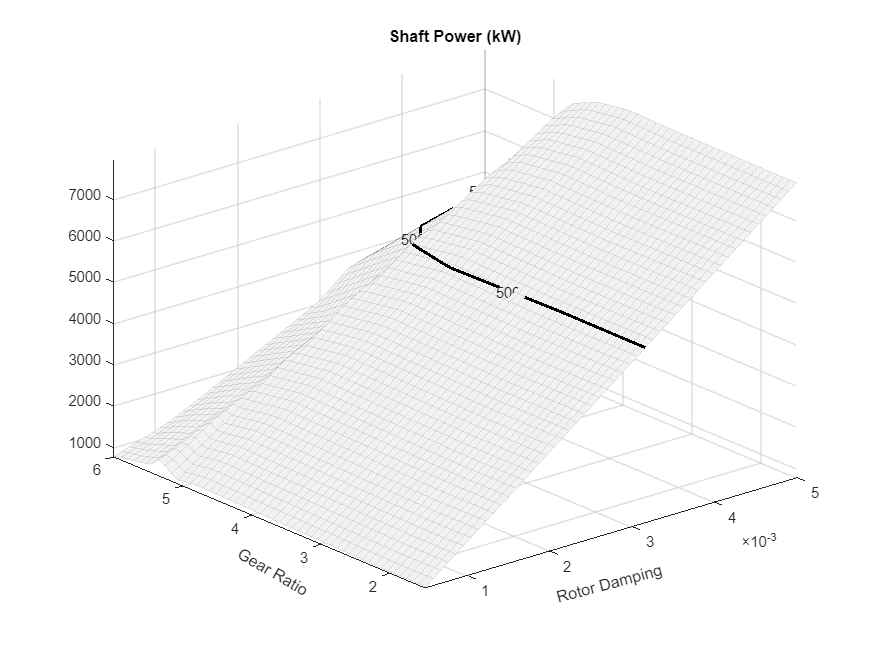

alphaFace = 1;
alphaEdge = 0.1;
xlabelRot = 15;
ylabelRot = -30;

% Create a custom coloring matrix C with different values for each objective function
C = zeros(size(responseShaftPower));  % Initialize with zeros
C(responseShaftPower >= constraint_ShaftPower) = 1;
% C1 = zeros(size(responseShaftPower));
C(responseThrustCore >= constraint_ThrustCore) = 0.5;
% C2 = zeros(size(responseShaftPower));
C(responseThrustPT >= constraint_ThrustPT) = 0.25;
C((responseShaftPower < constraint_ShaftPower) | (responseThrustCore < constraint_ThrustCore) | (responseThrustPT < constraint_ThrustPT)) = 0;


figure;
hSurf = surf(A,B,responseShaftPower,'FaceAlpha',alphaFace,'CData',C,'EdgeAlpha',alphaEdge);
% hold on 
% surf(A,B,responseShaftPower,'FaceAlpha',alphaFace,'CData',C1,'EdgeAlpha',alphaEdge);
% surf(A,B,responseShaftPower,'FaceAlpha',alphaFace,'CData',C2,'EdgeAlpha',alphaEdge);
% hold off
xlabel('Rotor Damping','Rotation',xlabelRot);
ylabel('Gear Ratio','Rotation',ylabelRot);
title('Shaft Power (kW)');

% colormap([0.9 0.9 0.9; 0 1 1; 1 0 0; 1 1 0; 0 1 0]);

% The colors transition from a cool teal to a warm pink, with intermediary colors.
customColormap = [
    0.95, 0.95, 0.95;   % Grey
    0.1, 0.6, 0.5;   % Teal
    0.2, 0.7, 0.8;   % Sky blue
    0.9, 0.8, 0.2;   % Sunflower yellow
    0.9, 0.5, 0.1;   % Orange
    0.8, 0.2, 0.5    % Pink
];

% Apply the custom colormap to the current figure
colormap(customColormap);



% % Decision boundary for Z = 0 (between positive and non-positive Z)
% % Find the contour where Z equals approximately zero
hold on
[cContour, hContour] = contour3(A,B,responseShaftPower, [constraint_ShaftPower constraint_ShaftPower], 'k', 'LineWidth', 2,'ShowText','on','FaceColor','none'); 


% Move the surf plot to the top of the stacking order
uistack(hSurf, 'top');

hold off
set(gcf,'Position',[10 10 800 600]);
view([-40 30])

# Multiobjective Optimization for Feasible Designs

If direct visualization of design space is difficult or the number of design parameters is simply too high, multi-objective optimization can be particularly helpful in finding pareto-optimal points. 

Pareto-optimal points are a group of points that trade off one objective function for the other and it is up to the design engineer to evaluate the fitness of these points.

### GA Multiobjective Optimization

The objectives for this optimization problem are:


$$\max_{9-\textrm{Vars}} {\textrm{Shaft}\;\textrm{Power}}_{\textrm{steady}-\textrm{state}}$$



$$\max_{9-\textrm{Vars}} {\textrm{Core}\;\textrm{Thrust}}_{\textrm{steady}-\textrm{state}}$$



$$\max_{9-\textrm{Vars}} {\textrm{PT}\;\textrm{Thrust}}_{\textrm{steady}-\textrm{state}}$$


Let us set up the optimization problem with a few constraints on the input design parameters as well as our constraints on the objective functions.

lower_bound = [designVar_CoreShaftInertia_lb; designVar_CoreDampingCoeff_lb; designVar_CombustorVolume_lb; designVar_PTInertiaMultiplier_lb;...
               designVar_RotorInertiaMultiplier_lb; designVar_PTNozzleOpening_lb; designVar_PTDampingCoeff_lb; designVar_RotorDampingCoeff_lb; designVar_GearRatio_lb];
upper_bound = [designVar_CoreShaftInertia_ub; designVar_CoreDampingCoeff_ub; designVar_CombustorVolume_ub; designVar_PTInertiaMultiplier_ub;...
               designVar_RotorInertiaMultiplier_ub; designVar_PTNozzleOpening_ub; designVar_PTDampingCoeff_ub; designVar_RotorDampingCoeff_ub; designVar_GearRatio_ub];


Define multi-objective function `mof(x)`. Here, the multi-objective function consists of 3 functions, which are respectively calling the AI models for predictions on 9 design variables. 

mof = @(x)[funcShaftPowerROM(NN_ShaftPower,x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9));...
          funcThrustCoreROM(NN_ThrustCore,x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9));...
          funcThrustPTROM(NN_ThrustPT,x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9))]

mof = function_handle with value:
    @(x)[funcShaftPowerROM(NN_ShaftPower,x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9));funcThrustCoreROM(NN_ThrustCore,x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9));funcThrustPTROM(NN_ThrustPT,x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9))]

Define other constraints. There are no linear inequality or equality constraints in this problem so they will be empty `[]`. 

% A = []; B = [];
% Aeq = []; Beq = [];

Since there are constraints on the cost functions, these can be interpreted as non-linear constraints in the optimization problem. The function `designconstraints` describes these.

nonlcon = @(x)designconstraints(NN_ShaftPower,NN_ThrustCore,NN_ThrustPT,constraints,x);

### Run Optimization

[x_opt,fval] = gamultiobj(mof,9,[],[],[],[],lower_bound,upper_bound,nonlcon)

gamultiobj stopped because the average change in the spread of Pareto solutions is less than options.FunctionTolerance.


x_opt =     0.3485    0.0019    0.0069    0.3926    0.3492    0.3386    0.0022    0.0034    3.2063
    0.2569    0.0019    0.0070    0.4091    0.2329    0.4879    0.0028    0.0032    3.7804
    0.2386    0.0022    0.0075    0.4223    0.5096    0.5114    0.0026    0.0032    3.7909
    0.3426    0.0017    0.0069    0.4017    0.4023    0.3548    0.0021    0.0037    3.1912
    0.2726    0.0018    0.0055    0.4290    0.4372    0.4916    0.0027    0.0032    3.8525
    0.2913    0.0017    0.0054    0.3199    0.3604    0.3567    0.0021    0.0043    2.9795
    0.2660    0.0016    0.0067    0.4288    0.3822    0.3782    0.0020    0.0036    3.0148
    0.3054    0.0017    0.0066    0.3583    0.3564    0.3584    0.0022    0.0039    2.9897
    0.2542    0.0013    0.0064    0.3847    0.5572    0.4209    0.0031    0.0032    3.9463
    0.2247    0.0048    0.0067    0.4150    0.4679    0.5138    0.0027    0.0032    3.7849


fval = 1.0e+03 *

    5.3578    0.1500    1.0942
    5.0003    0.2879    1.2144
    5.0017    0.2989    1.1706
    5.8332    0.1500    1.0728
    5.0004    0.2811    1.2131
    6.7667    0.1500    1.0523
    5.6518    0.1623    1.0001
    6.1489    0.1500    1.0546
    5.0001    0.2450    1.3556
    5.0000    0.4252    1.1542


### Visualize Optimization results

load gaOptimResults.mat

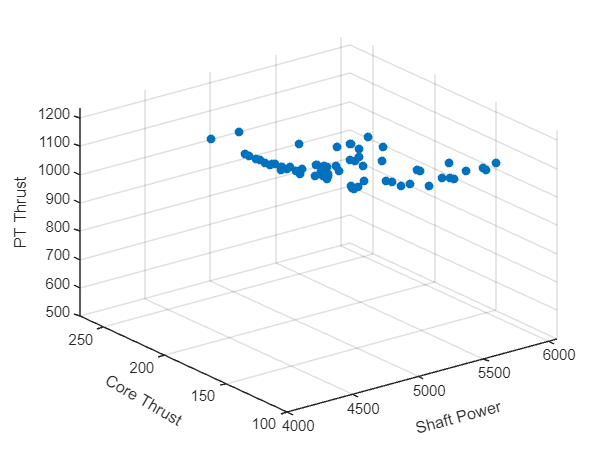

figure
scatter3(fval(:,1), fval(:,2), fval(:,3),'o','filled')
xlabel('Shaft Power','Rotation',15)
ylabel('Core Thrust','rotation',-30,'HorizontalAlignment','right')
zlabel('PT Thrust')
zlim([constraint_ThrustPT-500 inf])
ylim([constraint_ThrustCore-50 inf])
xlim([constraint_ShaftPower-1000 inf])

### Helper Functions

This section contains helper functions defined for specific tasks in the previous sections.

function shaftPower = funcShaftPowerROM(mdl,CoreInertia,CoreDamping,CombustorVolume,PTInertiaMultiplier,RotorInertiaMultiplier,PTNozzleOpening,PTDamping,RotorDamping,GearRatio)
    tbl2 = table(0,0,0,0,0,0,0,0,0,'VariableNames',{'CoreInertia','CoreDamping','CombustorVolume','PTInertia','RotorInertia','PTNozzleOpening','PTDamping','RotorDamping','GearRatio'});
    tbl2.CoreInertia = CoreInertia;
    tbl2.CoreDamping = CoreDamping;
    tbl2.CombustorVolume = CombustorVolume;
    tbl2.PTInertia = CoreInertia .* PTInertiaMultiplier;
    tbl2.RotorInertia = CoreInertia .* RotorInertiaMultiplier;
    tbl2.PTNozzleOpening = PTNozzleOpening;
    tbl2.PTDamping = PTDamping;
    tbl2.RotorDamping = RotorDamping;
    tbl2.GearRatio = GearRatio;
    shaftPower = mdl.predictFcn(tbl2);
end

function thrustCore = funcThrustCoreROM(mdl,CoreInertia,CoreDamping,CombustorVolume,PTInertiaMultiplier,RotorInertiaMultiplier,PTNozzleOpening,PTDamping,RotorDamping,GearRatio)
    tbl2 = table(0,0,0,0,0,0,0,0,0,'VariableNames',{'CoreInertia','CoreDamping','CombustorVolume','PTInertia','RotorInertia','PTNozzleOpening','PTDamping','RotorDamping','GearRatio'});
    tbl2.CoreInertia = CoreInertia;
    tbl2.CoreDamping = CoreDamping;
    tbl2.CombustorVolume = CombustorVolume;
    tbl2.PTInertia = CoreInertia .* PTInertiaMultiplier;
    tbl2.RotorInertia = CoreInertia .* RotorInertiaMultiplier;
    tbl2.PTNozzleOpening = PTNozzleOpening;
    tbl2.PTDamping = PTDamping;
    tbl2.RotorDamping = RotorDamping;
    tbl2.GearRatio = GearRatio;
    thrustCore = mdl.predictFcn(tbl2);
end

function thrustPT = funcThrustPTROM(mdl,CoreInertia,CoreDamping,CombustorVolume,PTInertiaMultiplier,RotorInertiaMultiplier,PTNozzleOpening,PTDamping,RotorDamping,GearRatio)
    tbl2 = table(0,0,0,0,0,0,0,0,0,'VariableNames',{'CoreInertia','CoreDamping','CombustorVolume','PTInertia','RotorInertia','PTNozzleOpening','PTDamping','RotorDamping','GearRatio'});
    tbl2.CoreInertia = CoreInertia;
    tbl2.CoreDamping = CoreDamping;
    tbl2.CombustorVolume = CombustorVolume;
    tbl2.PTInertia = CoreInertia .* PTInertiaMultiplier;
    tbl2.RotorInertia = CoreInertia .* RotorInertiaMultiplier;
    tbl2.PTNozzleOpening = PTNozzleOpening;
    tbl2.PTDamping = PTDamping;
    tbl2.RotorDamping = RotorDamping;
    tbl2.GearRatio = GearRatio;
    thrustPT = mdl.predictFcn(tbl2);
end

function [c,ceq] = designconstraints(mdlSP,mdlTC,mdlTPT,constraints,x)
    c(1) = funcShaftPowerROM(mdlSP,x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9)) <= constraints(1);
    c(2) = funcThrustCoreROM(mdlTC,x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9)) <= constraints(2);
    c(3) = funcThrustPTROM(mdlTPT,x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9)) <= constraints(3);
    ceq = []; % No non-linear equality constraints
end